- **Plot the spectra - Discuss their frequency content and relate to the auditory range of human hearing**

The auditory range of humans is 20Hz to 20kHz.

The frequency content of all the following signals were between this range. on using the command "soundsc(signal)" , we could hear the sound.

However, when the frequency band was either brought below ~10Hz (ideally 20Hz) or above 20kHz, a sound could not be heard.

## Sine

clear all; close all; clc;
t = 0 : 1/1000 : 0.1;
f1 = 30; 
% f1 = 10Hz
T1 = 1/f1;
amp1 = 1; 
signal = amp1 * sin(2*pi*t/T1);

Y=fft(signal);
L = length (signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

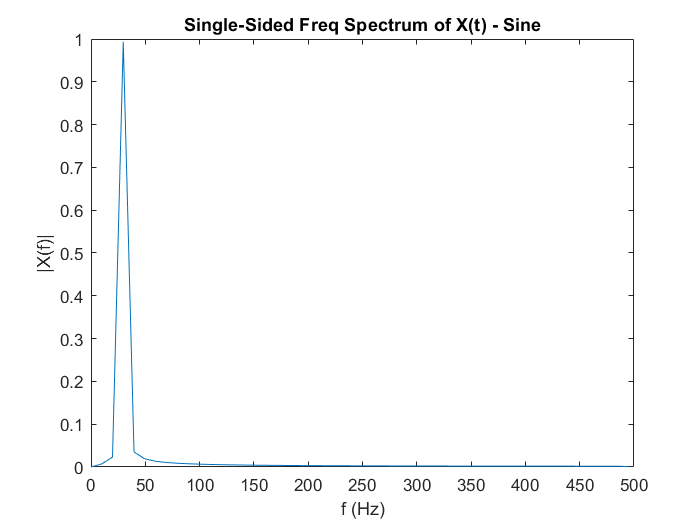

P1(2:end-1) = 2*P1(2:end-1);
f = 1000*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Freq Spectrum of X(t) - Sine')
xlabel('f (Hz)')
ylabel('|X(f)|')

%soundsc(signal)


## Log Chirp

t= 0:0.001:10; 
fo=10;f1=400;
signal=chirp(t,fo,10,f1,'logarithmic');

Y=fft(signal);
L = length (signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

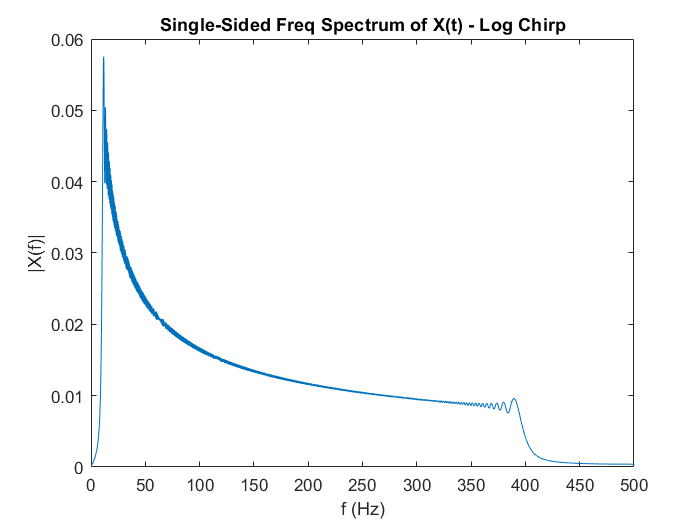

P1(2:end-1) = 2*P1(2:end-1);
f = 1000*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Freq Spectrum of X(t) - Log Chirp')
xlabel('f (Hz)')
ylabel('|X(f)|')

## Quadratic Chirp

t=0:0.001:2;                  
signal=chirp(t,10,1,100,'q');

Y=fft(signal);
L = length (signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

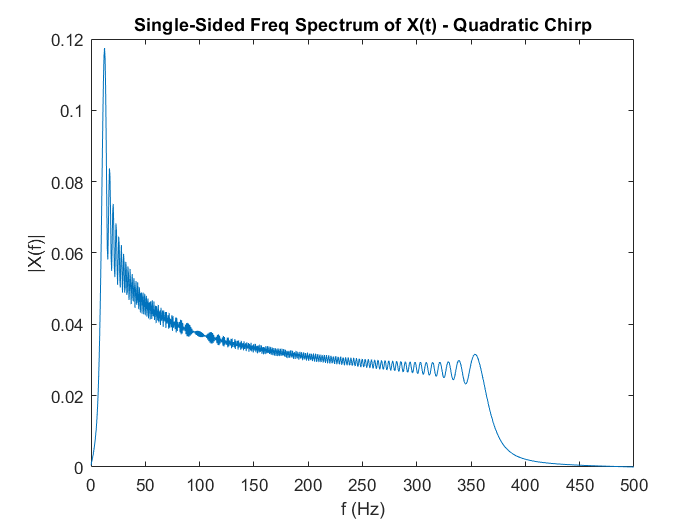

P1(2:end-1) = 2*P1(2:end-1);
f = 1000*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Freq Spectrum of X(t) - Quadratic Chirp')
xlabel('f (Hz)')
ylabel('|X(f)|')

## Linear Chirp

t=0:0.001:2; 
signal=chirp(t,0,1,150, 'linear');  

Y=fft(signal);
L = length (signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

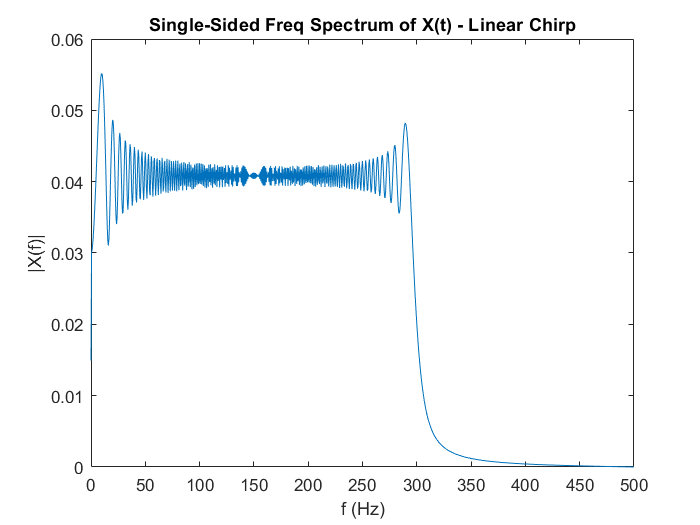

P1(2:end-1) = 2*P1(2:end-1);
f = 1000*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Freq Spectrum of X(t) - Linear Chirp')
xlabel('f (Hz)')
ylabel('|X(f)|')

## Concave Chirp

t= 0:0.0001:2;
y=chirp(t,100,1,25,'q',[],'concave');

Y=fft(signal);
L = length (signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

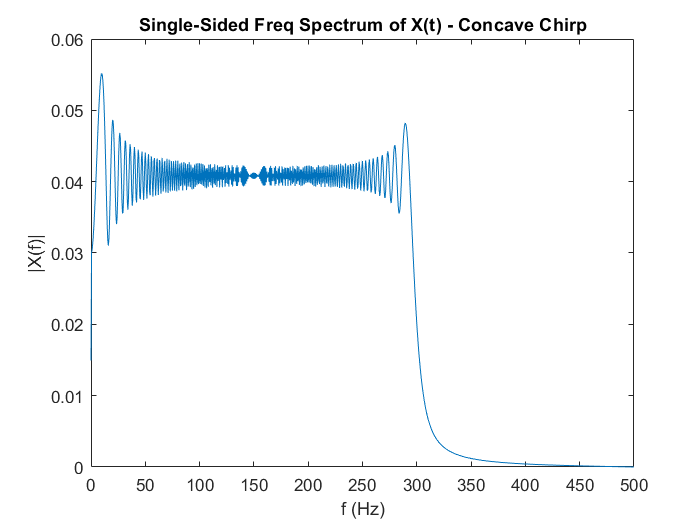

P1(2:end-1) = 2*P1(2:end-1);
f = 1000*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Freq Spectrum of X(t) - Concave Chirp')
xlabel('f (Hz)')
ylabel('|X(f)|')